# Comaracion de Metodos de Integración Numerica

- Iniciamos el programa

- Cargamos datos

clear all,close all, clc
load("sr_90data.mat")

- Extraemos los datos a leer y creamos sus varaiables de almacenamiento

- Conversion de unidades $f(x)=f_{b} * 1ms=f_{b}*1*10^{-3}$

- Regla de tres $f^{'}_{x}=\left[ \matrix{
2^{15} \rightarrow 1000 \frac{\degree }{s}
\cr
{f(x) \rightarrow x}}

\right]$

t=(transpose(datosr90(:,2)));     %Tiempo
f_brute=(transpose(datosr90(:,1))).*1*10^(-3);     %Funcion a integrar
%t=linspace(0,2*pi,100);
%f=(t);
f=(f_brute.*1000)./(2^15/2);
[a,b]=size(f);                  %Tamaño de la funcion 
w=zeros(a,b);                   %vector a guardar la Integral en ceros
w1=zeros(a,b);         

## Regla del Trapecio

for i=2:b-1
    w(1,i)=w(1,i-1)+trapecio_intg([t(1,i),t(1,i+1)],[f(1,i),f(1,i+1)]);
end

%Plot funcion
plot(t,f,'b')
hold on
%Plot Integral numerica
plot(t(1,1:b-1),w(1,1:b-1),'r')

## Regla de Simpson 1/3

for i=2:b-2
    w1(1,i)=w1(1,i-1)+rule_simp13([t(1,i),t(1,i+2)],[f(1,i),f(1,i+1),f(1,i+2)]);
end

hold on
%Plot Integral numerica
plot(t(1,1:b-2),w1(1,1:b-2),'g')

## Regla de Simpson 3/8

for i=2:b-3
    w(1,i)=w(1,i-1)+rule_simp38([t(1,i),t(1,i+3)],[f(1,i),f(1,i+1),f(1,i+2),f(1,i+3)]);
end

hold on
%Plot Integral numerica
plot(t(1,1:b-3),w(1,1:b-3),'k')
w(1,1)=0;

## Regla de Boole

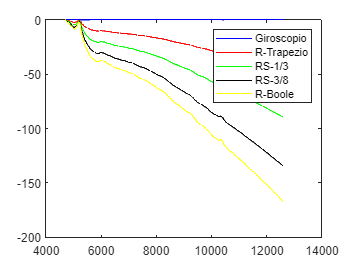

for i=2:b-4
    w(1,i)=w(1,i-1)+rule_boole([t(1,i),t(1,i+4)],[f(1,i),f(1,i+1),f(1,i+2),f(1,i+3),f(1,i+4)]);
end

hold on
%Plot Integral numerica
plot(t(1,1:b-4),w(1,1:b-4),'y')
legend('Giroscopio','R-Trapezio','RS-1/3','RS-3/8','R-Boole')

%ylim([-20*10^5,5*10^5])